# EEE 424 - Coding Assignment 1 - FFT Algorithms

Tuna Şahin - 22201730 - EEE 424-1

## Question 1

Q1) Creation of random N = 32 complex valued array. The radix-2 fft functions that I wrote are available at the end of the page.

rng(2,"twister");
N = 32;
real_part = randn(1,N);
imag_part = randn(1,N);
x = real_part + 1i*imag_part;

W = tfft(x) - fft(x);

a) plotting x[n] 

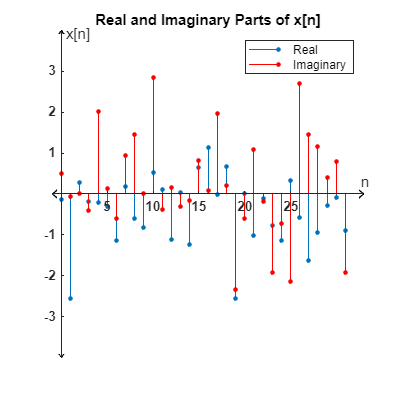

clf;
ns = linspace(0,N-1,N);
stem(ns,real(x),'filled','MarkerSize',3)
hold on
finestem(ns,imag(x),'Real and Imaginary Parts of x[n]','n','x[n]',[-1 33],[-4 4],'off',[400 400],'','r-');
legend('Real','Imaginary')

b) using the direct summation form:

tic
dft_x = ns*0;
for i = 1:N
    dft_x = dft_x + x(i) * exp((i-1)*-2j*pi/N).^ns;
end
time_direct_summation_32 = toc;

The variable "dft_x" now holds the DFT of x!

c) we already calculated the basis vectors in the previous part! just concatenate them together:

tic
dft_m = zeros([32,32]);
for i = 1:N
    dft_m(i,1:end) = exp((i-1)*-2j*pi/N).^ns;
end
time_DFT_matrix_gen_32 = toc;

The variable "dtf_m" now holds a DFT matrix of size 32!

d) we simply perform a multiplication to calculate the DFT from the DFT matrix.

tic
dft_x_2 = dft_m * x.'; %transpose it to make it a vector
time_matrix_multiplication_32 = toc;
dft_x_2 = dft_x_2.';

The variable "dtf_x_2" now holds the DFT of x that we calculated using the DFT matrix.

e)The function "tfft" which stands for "time fast fourier transform" is available at the end of the file. Calculate the fft of x using the function as:

tic
tfft_x = tfft(x);
time_DIT_FFT_32 = toc;

f)The function "ffft" which stands for "frequency fast fourier transform" is available at the end of the file. Calculate the fft of x using the function as:

tic
ffft_x = ffft(x);
time_DIf_FFT_32 = toc;

g) simply use the fft command to calculate it.

tic
fft_x = fft(x);
time_MATLAB_FFT_32 = toc;

h) compare all the results in a subplot and also the difference of their norms

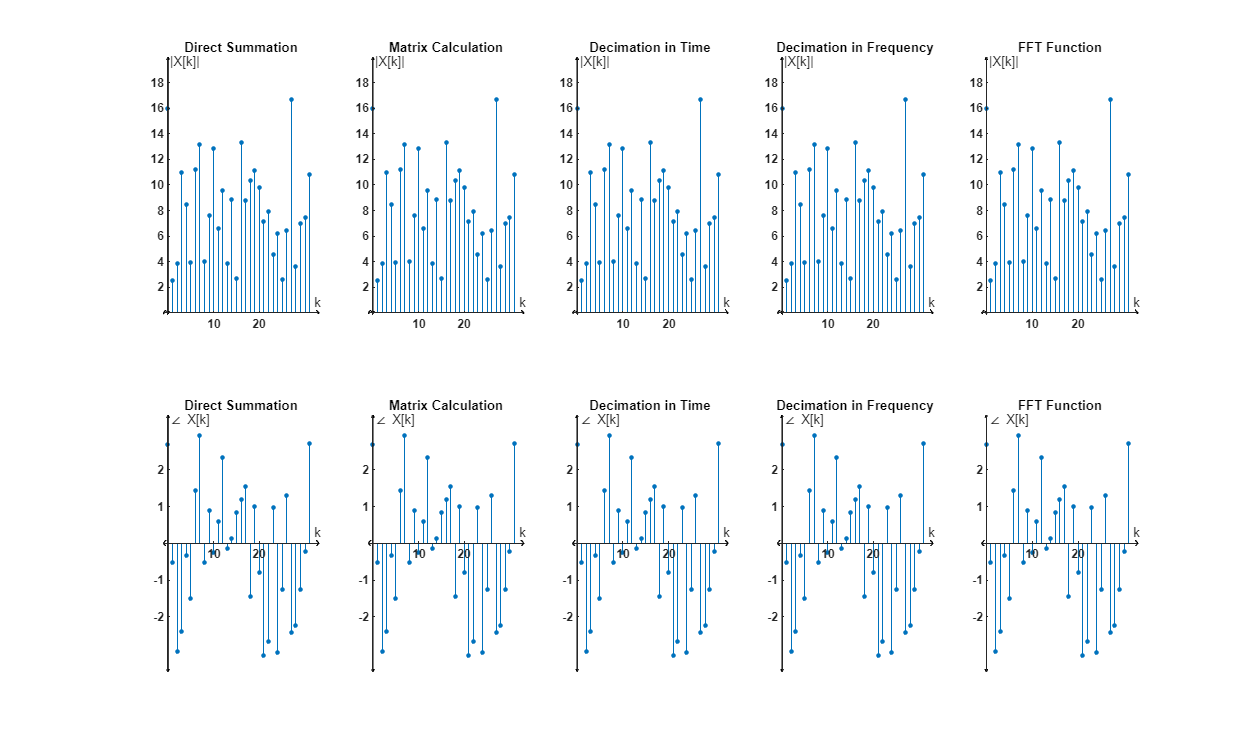

clf;
dfts = [dft_x ; dft_x_2 ; tfft_x ; ffft_x ; fft_x];
names = [" Direct Summation "," Matrix Calculation "," Decimation in Time "," Decimation in Frequency "," FFT Function "];
for i = 1:5
 subplot(2,5,i)
 finestem(ns,abs(dfts(i,1:end)),names(i),'k','|X[k]|',[-1 33],[-0.1 20],'off',[1500 900],'','o-');
 subplot(2,5,5+i)
 finestem(ns,angle(dfts(i,1:end)),names(i),'k','\angle X[k]',[-1 33],[-3.5 3.5],'off',[1500 900],'','o-');
end

The following code loops over all possible method combinations and performs the $\textrm{norm}\left(y_{{\textrm{method}}_1 } -y_{{\textrm{method}}_2 } \right)$ operation on each pair. We can observe that each element of the array is on the order of ${10}^{-13} \ldotp$

Es = [];
for i = 1:5
    for j = i+1:5
        Es = [Es norm(dfts(i,1:end)-dfts(j,1:end))];
    end
end
disp(array2table([Es(1:5);Es(6:10)]))

       Var1          Var2          Var3          Var4          Var5   
    __________    __________    __________    __________    __________

    2.3133e-13    2.4991e-13    2.4404e-13    2.4773e-13    2.6117e-13
    2.5829e-13    2.6028e-13    1.8855e-14    1.3463e-14    1.5057e-14



||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||

i) We are asked to repeat the above steps for N = 256:

Generation of the Array

rng(2,"twister");
N_256 = 256;
real_part = randn(1,N_256);
imag_part = randn(1,N_256);
x_256 = real_part + 1i*imag_part;

Plotting of the Array:

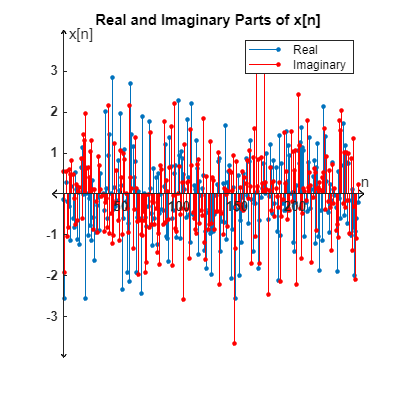

clf;
ns_256 = linspace(0,N_256-1,N_256);
stem(ns_256,real(x_256),'filled','MarkerSize',3)
hold on
finestem(ns_256,imag(x_256),'Real and Imaginary Parts of x[n]','n','x[n]',[-10 260],[-4 4],'off',[400 400],'','r-');
legend('Real','Imaginary')

Direct Summation Method:

tic
dft_x_256 = ns_256*0;
for i = 1:N_256
    dft_x_256 = dft_x_256 + x_256(i) * exp((i-1)*-2j*pi/N_256).^ns_256;
end
time_direct_summation_256 = toc;

DFT Matrix Generation:

tic
dft_m_256 = zeros([N_256,N_256]);
for i = 1:N_256
    dft_m_256(i,1:end) = exp((i-1)*-2j*pi/N_256).^ns_256;
end
time_DFT_matrix_gen_256 = toc;

Multiplication with the DFT Matrix:

tic
dft_x_2_256 = dft_m_256 * x_256.'; %transpose it to make it a vector
time_matrix_multiplication_256 = toc;
dft_x_2_256 = dft_x_2_256.';

Decimation in Time Algorithm:

tic
tfft_x_256 = tfft(x_256);
time_DIT_FFT_256 = toc;

Decimation in Frequency Algorithm:

tic
ffft_x_256 = ffft(x_256);
time_DIf_FFT_256 = toc;

MATLAB's FFT Funciton:

tic
fft_x_256 = fft(x_256);
time_MATLAB_FFT_256 = toc;

Creating the Subplots for Comparison:

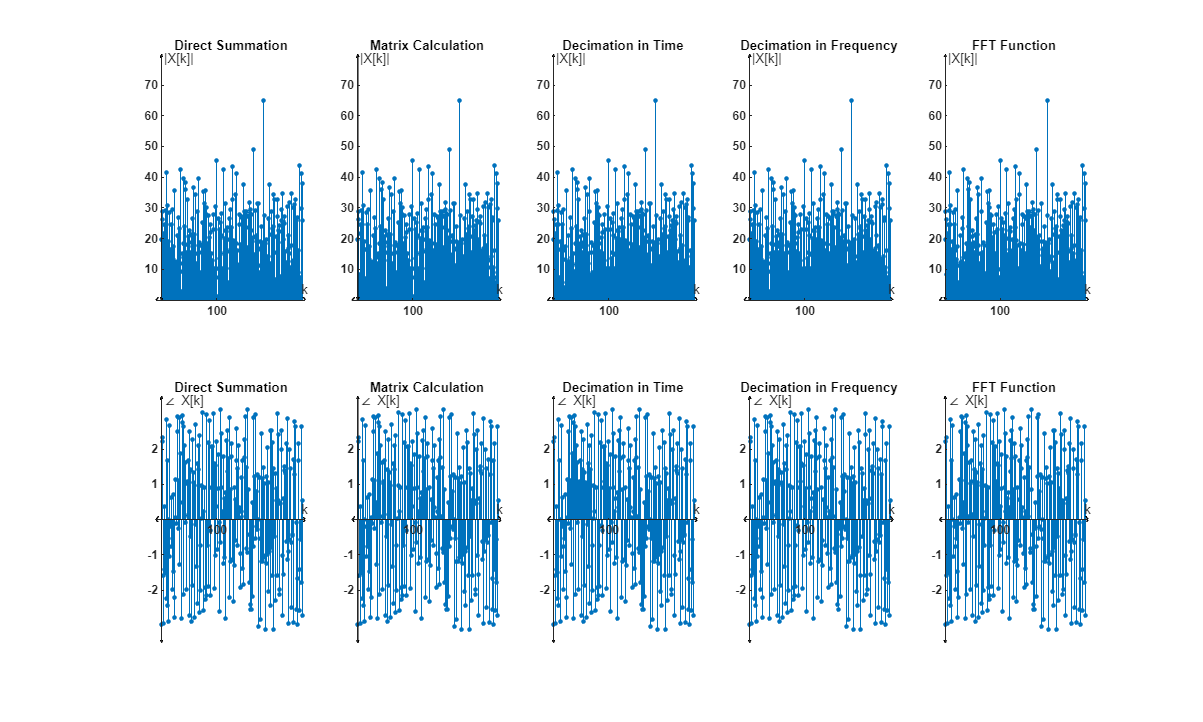

clf;
dfts = [dft_x_256 ; dft_x_2_256 ; tfft_x_256 ; ffft_x_256 ; fft_x_256];
names = [" Direct Summation "," Matrix Calculation "," Decimation in Time "," Decimation in Frequency "," FFT Function "];
for i = 1:5
 subplot(2,5,i)
 finestem(ns_256,abs(dfts(i,1:end)),names(i),'k','|X[k]|',[-10 260],[-0.1 80],'off',[1500 900],'','o-');
 subplot(2,5,5+i)
 finestem(ns_256,angle(dfts(i,1:end)),names(i),'k','\angle X[k]',[-10 260],[-3.5 3.5],'off',[1500 900],'','o-');
end

Calculating the Norms of the Differences:

Es = [];
for i = 1:5
    for j = i+1:5
        Es = [Es norm(dfts(i,1:end)-dfts(j,1:end))];
    end
end
disp(array2table([Es(1:5);Es(6:10)]))

       Var1          Var2          Var3          Var4          Var5   
    __________    __________    __________    __________    __________

    1.4713e-11    1.2639e-11    1.2668e-11    1.2703e-11    1.3349e-11
    1.3328e-11    1.3389e-11    5.5926e-13    6.0412e-13    5.5252e-13



|||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||

j) We are asked to repeat the above steps for N = 4096:

Generation of the Array

rng(2,"twister");
N_4096 = 2^12;
real_part = randn(1,N_4096);
imag_part = randn(1,N_4096);
x_4096 = real_part + 1i*imag_part;

Plotting of the Array:

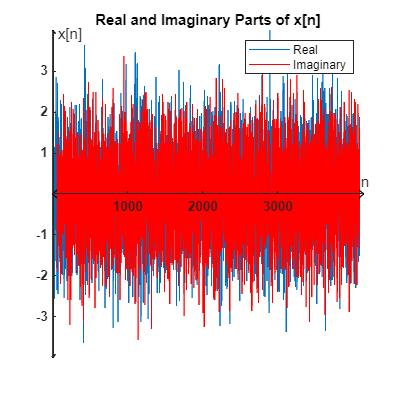

clf;
ns_4096 = linspace(0,N_4096-1,N_4096);
plot(ns_4096,real(x_4096))
hold on
fineplot(ns_4096,imag(x_4096),'Real and Imaginary Parts of x[n]','n','x[n]',[-10 4150],[-4 4],'off',[400 400],'','r-');
legend('Real','Imaginary')

Direct Summation Method:

tic
dft_x_4096 = ns_4096*0;
for i = 1:N_4096
    dft_x_4096 = dft_x_4096 + x_4096(i) * exp((i-1)*-2j*pi/N_4096).^ns_4096;
end
time_direct_summation_4096 = toc;

DFT Matrix Generation:

tic
dft_m_4096 = zeros([N_4096,N_4096]);
for i = 1:N_4096
    dft_m_4096(i,1:end) = exp((i-1)*-2j*pi/N_4096).^ns_4096;
end
time_DFT_matrix_gen_4096 = toc;

Multiplication with the DFT Matrix:

tic
dft_x_2_4096 = dft_m_4096 * x_4096.'; %transpose it to make it a vector
time_matrix_multiplication_4096 = toc;
dft_x_2_4096 = dft_x_2_4096.';

Decimation in Time Algorithm:

tic
tfft_x_4096 = tfft(x_4096);
time_DIT_FFT_4096 = toc;

Decimation in Frequency Algorithm:

tic
ffft_x_4096 = ffft(x_4096);
time_DIf_FFT_4096 = toc;

MATLAB's FFT Funciton:

tic
fft_x_4096 = fft(x_4096);
time_MATLAB_FFT_4096 = toc;

Creating the Subplots for Comparison: The plots become redundant due to the high number of data. However, difference norm test still provides a good understanding.

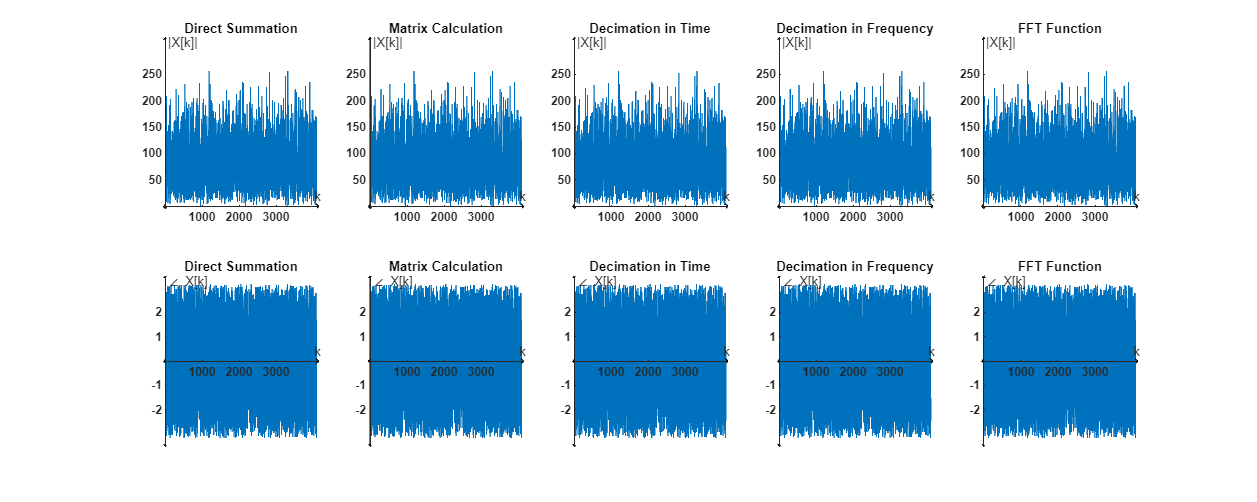

clf;
dfts = [dft_x_4096 ; dft_x_2_4096 ; tfft_x_4096 ; ffft_x_4096 ; fft_x_4096];
names = [" Direct Summation "," Matrix Calculation "," Decimation in Time "," Decimation in Frequency "," FFT Function "];
for i = 1:5
    subplot(2,5,i)
    fineplot(ns_4096,abs(dfts(i,1:end)),names(i),'k','|X[k]|',[-50 4150],[-5 320],'off',[1500 600],'','-');
    subplot(2,5,5+i)
    fineplot(ns_4096,angle(dfts(i,1:end)),names(i),'k','\angle X[k]',[-50 4150],[-3.5 3.5],'off',[1500 600],'','-');
end

Calculating the Norms of the Differences:

Es = [];
for i = 1:5
    for j = i+1:5
        Es = [Es norm(dfts(i,1:end)-dfts(j,1:end))];
    end
end
disp(array2table([Es(1:5);Es(6:10)]))

       Var1          Var2          Var3          Var4          Var5   
    __________    __________    __________    __________    __________

    3.5323e-09    3.2078e-09     3.212e-09     3.206e-09    3.1733e-09
    3.1739e-09    3.1691e-09    2.2256e-10    1.7131e-10    1.7114e-10



k) We are asked to compare the efficiencies of each approach. We measured the times of the methods using the "tic toc" function as we went along. We just need to compile the data into a table as:

Part_k = {'' 'N=32' 'N=256' 'N=2^12'; 'Direct Summation ' time_direct_summation_32 time_direct_summation_256 time_direct_summation_4096 ; 'DFT Matrix Generation' time_DFT_matrix_gen_32 time_DFT_matrix_gen_256 time_DFT_matrix_gen_4096 ; 'DFT Matrix ' time_matrix_multiplication_32 time_matrix_multiplication_256 time_matrix_multiplication_4096 ; 'Decimation in Time ' time_DIT_FFT_32 time_DIT_FFT_256 time_DIT_FFT_4096 ; 'Decimation in Frequency ' time_DIf_FFT_32 time_DIf_FFT_256 time_DIf_FFT_4096 ; 'MATLAB FFT ' time_MATLAB_FFT_32 time_MATLAB_FFT_256 time_MATLAB_FFT_4096}

Part_k = 7×4 cell array
    {0×0 char                  }    {'N=32'  }    {'N=256' }    {'N=2^12'}
    {'Direct Summation '       }    {[0.0051]}    {[0.0087]}    {[0.6096]}
    {'DFT Matrix Generation'   }    {[0.0044]}    {[0.0092]}    {[0.9492]}
    {'DFT Matrix '             }    {[0.0015]}    {[0.0014]}    {[0.0187]}
    {'Decimation in Time '     }    {[0.0033]}    {[0.0089]}    {[0.0378]}
    {'Decimation in Frequency '}    {[0.0093]}    {[0.0115]}    {[0.0516]}
    {'MATLAB FFT '             }    {[0.0014]}    {[0.0014]}    {[0.0019]}


We did not expect the DFT Matrix method, which is $O\left(n^2 \right)$, to be faster than the Decimation in Time method, which is $O\left(n\;\log \;n\right)$. If we include the generation time of the matrix however, it again takes longer than the FFT algorithms. Failure to optimise may have also resulted in this result. MATLAB may also have an internal optimisation for multiplication with a symmetric matrix.

# The FFT functions that i wrote:

Decimation in time algorithm for $2^n$ length array:

function X = tfft(x,n)
    arguments
        x (1,:) double
        n (1,1) double = length(x)
    end
    x = [x zeros([1,n-length(x)])];
    if isscalar(x)
        X = x;
    else
        w = exp(-j*2*pi/n); 
        X1 = tfft(x(1:2:end),n/2);
        X2 = tfft(x(2:2:end),n/2).*(w.^linspace(0,(n/2)-1,n/2));
        X = [X1+X2 X1-X2];
    end
end

Decimation in frequency algorithm for $2^n$ length array:

function X = ffft(x,n)
    arguments
        x (1,:) double
        n (1,1) double = length(x)
    end
    x = [x zeros([1,n-length(x)])];
    if isscalar(x)
        X = x;
    else
        w = exp(-j*2*pi/n); 
        x1 = x(1:end/2)+x(end/2+1:end);
        x2 = x(1:end/2)-x(end/2+1:end);

        X1 = ffft(x1);
        X2 = ffft(x2.*(w.^linspace(0,(n/2)-1,n/2)));
        
        X = zeros([1,n]);
        for i = 1:length(X1)
            X(2*i-1) = X1(i);
            X(2*i)   = X2(i);
        end
    end
end